# EX. 1. 

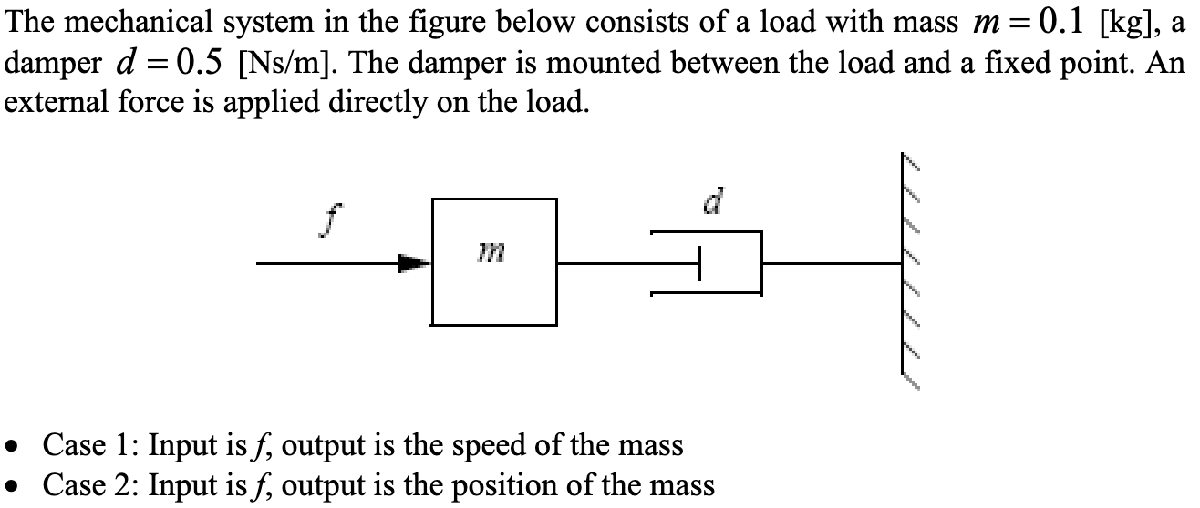

### What is the order of the model if the input is f and the output is the speed of the mass?

In this case the system can be described by the formula: $m \dot{v} = f - dv
$ which can be rewritten as: $\dot{v} + \frac{d}{m} v = \frac{f}{m}
$. The highest derivative of the output here is the first derivative and therefore the model is of order 1.

If the output is the position of the mass, what is the order again?

In this case the system can be described by: $m \ddot{x} = f - d \dot{x}
$ which can be rewritten as: $\ddot{x} + \frac{d}{m} \dot{x} = \frac{f}{m}

$. The highest derivative of the output here is the second derivative and therefore the model is of order 2. 

### Basic parameters

The basic parameters of the system are given in the problem description

m = 0.1; % kg
d = 0.5; % Ns/m

### State space and transfer function models

The state space models and transfer functions were derived on paper according to the following: 

Case 1: 

State space model:


$$% Define the state-space matrices using brackets
A = [\frac{-d}{m}]\ % A matrix (1-by-1)
B = [\frac{1}{m}]\    % B matrix (1-by-1)
C = [1]\      % C matrix (1-by-1, output = v)
D = [0]\      % D matrix (1-by-1)
$$


Transfer function model: 


$$G_1(s) = \frac{1}{m s + d}
$$


% Derived state space model for case 1:

A = -d/m;

B = 1/m;

% u = F

C1 = 1;

D = 0;

sys1 = ss(A, B, C1, D);

% Derived transfer function model for velocity output

s = tf('s');

G1 = 1 / (m*s + d);

Case 2: 

State space model:


$$A = \left( \matrix{0 & 1 \cr 0 & -\frac{d}{m}} \right), \quad
B = \left( \matrix{0 \cr \frac{1}{m}} \right), \quad
C = \left( \matrix{1 & 0} \right), \quad
D = 0
$$


Transfer function model: 


$$G_2(s) = \frac{1}{m s^2 + d s}

$$


% Derived state space model for case 2:

A = [0, 1; 0, -d/m];

B = [0; 1/m];

C2 = [1, 0];

D = 0;

sys2 = ss(A, B, C2, D);

% Derived transfer function model for position output
G2 = 1 / (m*s^2 + d*s);

### Frequency response

The frequency response (bode) for the models is shown below

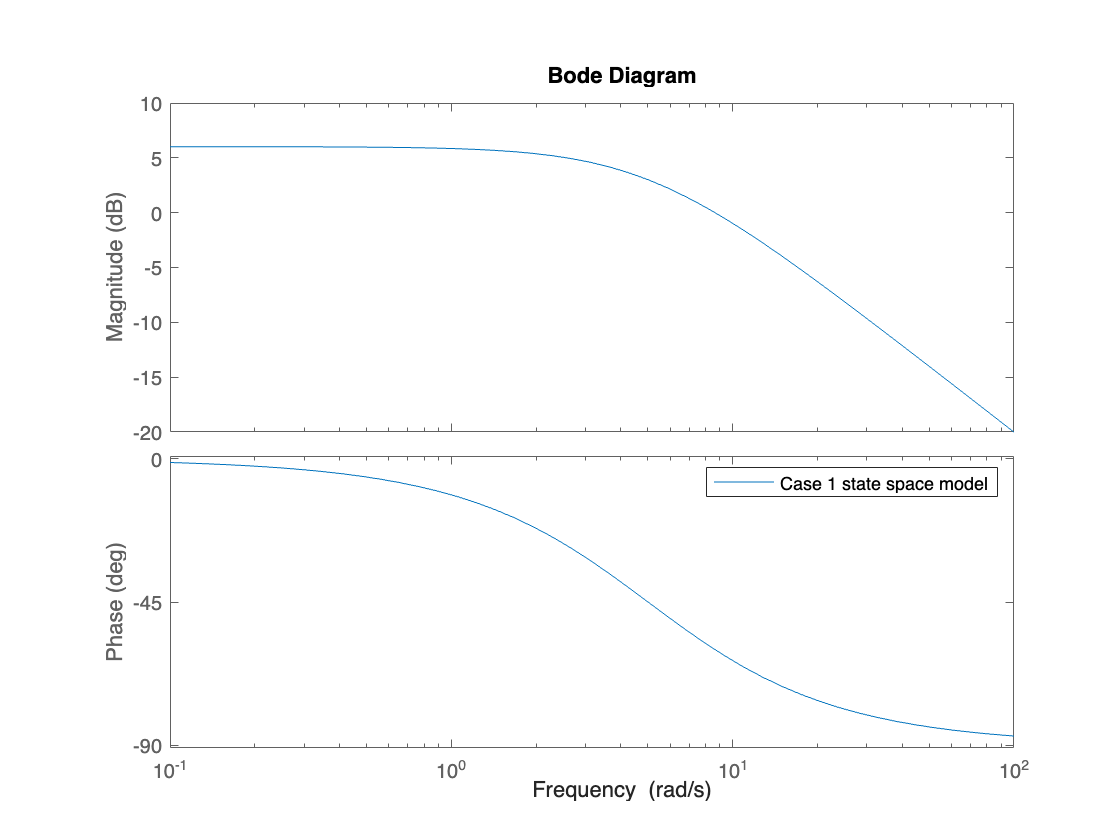

bode(sys1)
legend("Case 1 state space model")

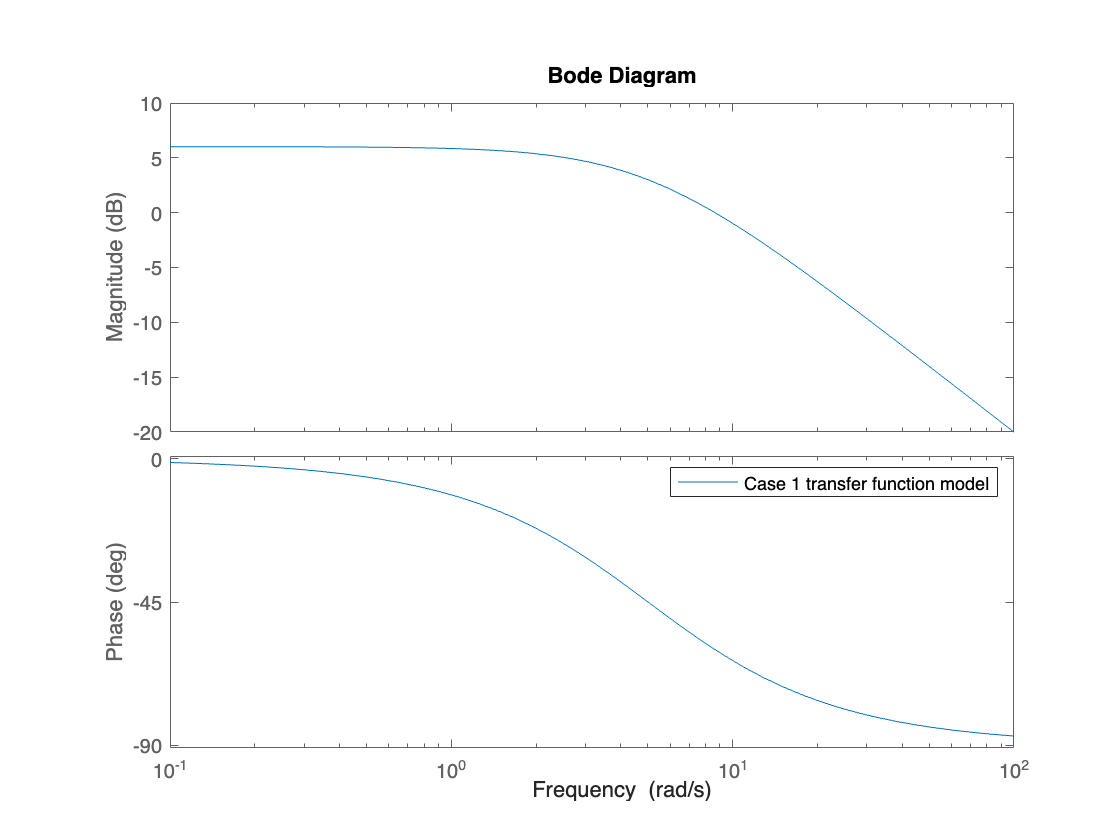

bode(G1)
legend("Case 1 transfer function model")

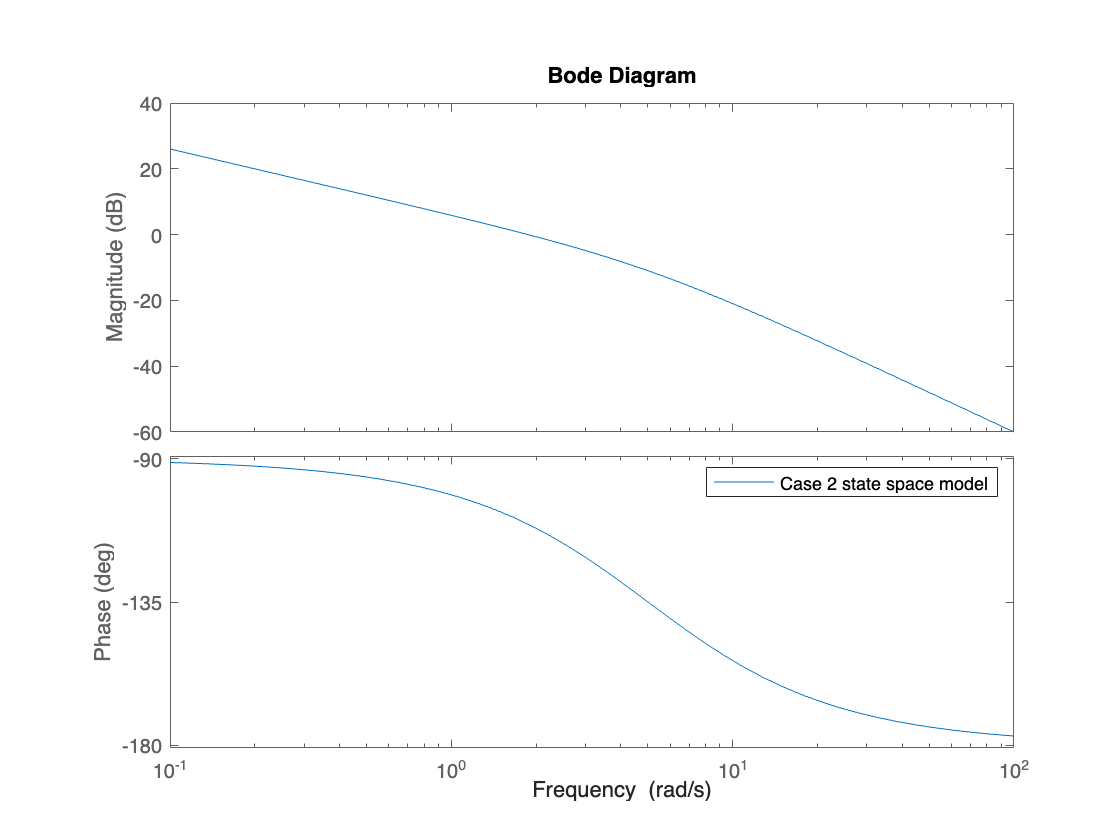

bode(sys2)
legend("Case 2 state space model")

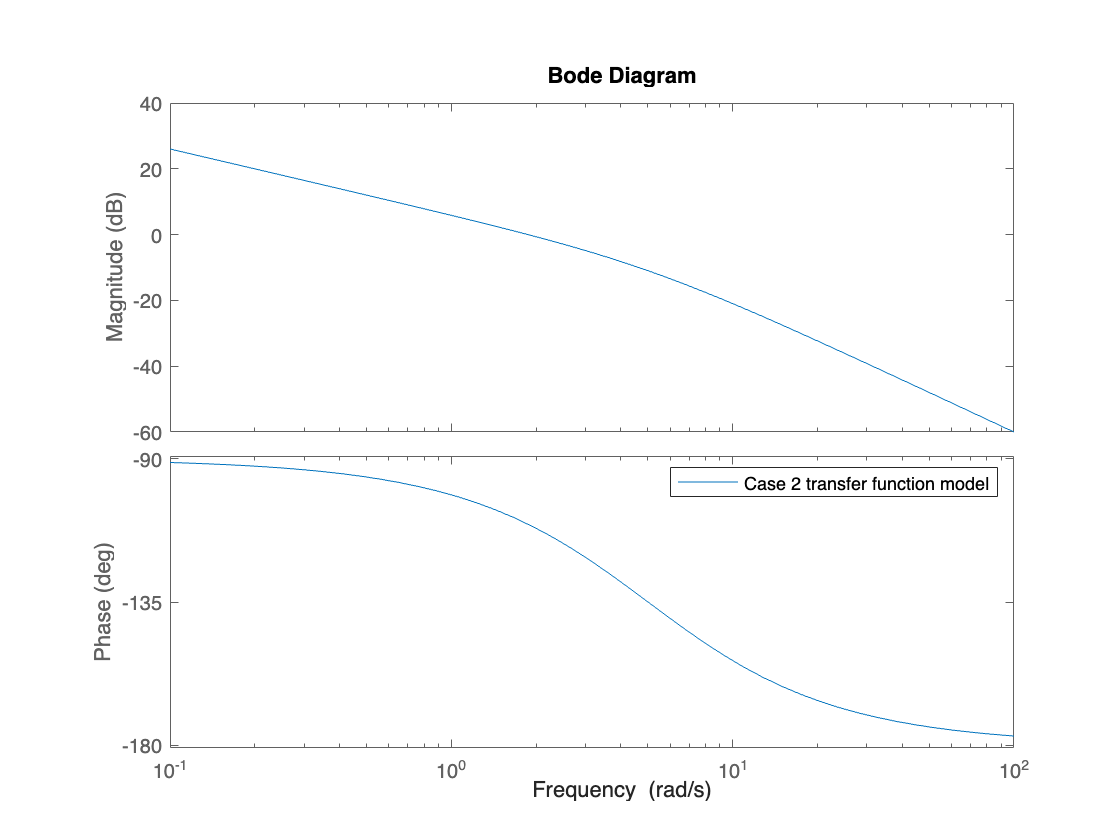

bode(G2)
legend("Case 2 transfer function model")

### Step response

The step response of the systems are shown below

Step response of system with velocity as output:

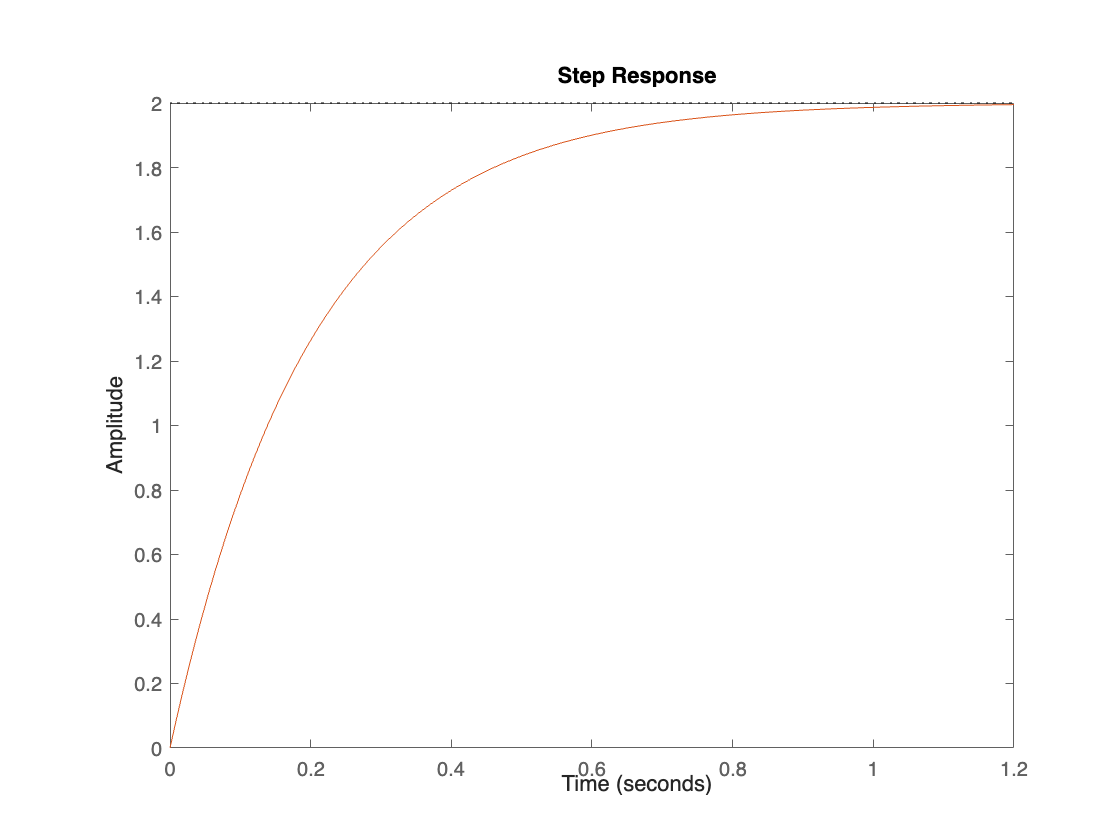


sp =

	resppack.timeplot



sp = stepplot(sys1, G1)

As can be seen in the graph, the amplitude of the velocity reaches a maximum at 2 m/s. This appears feasible. 

Step response of a system with position as output:

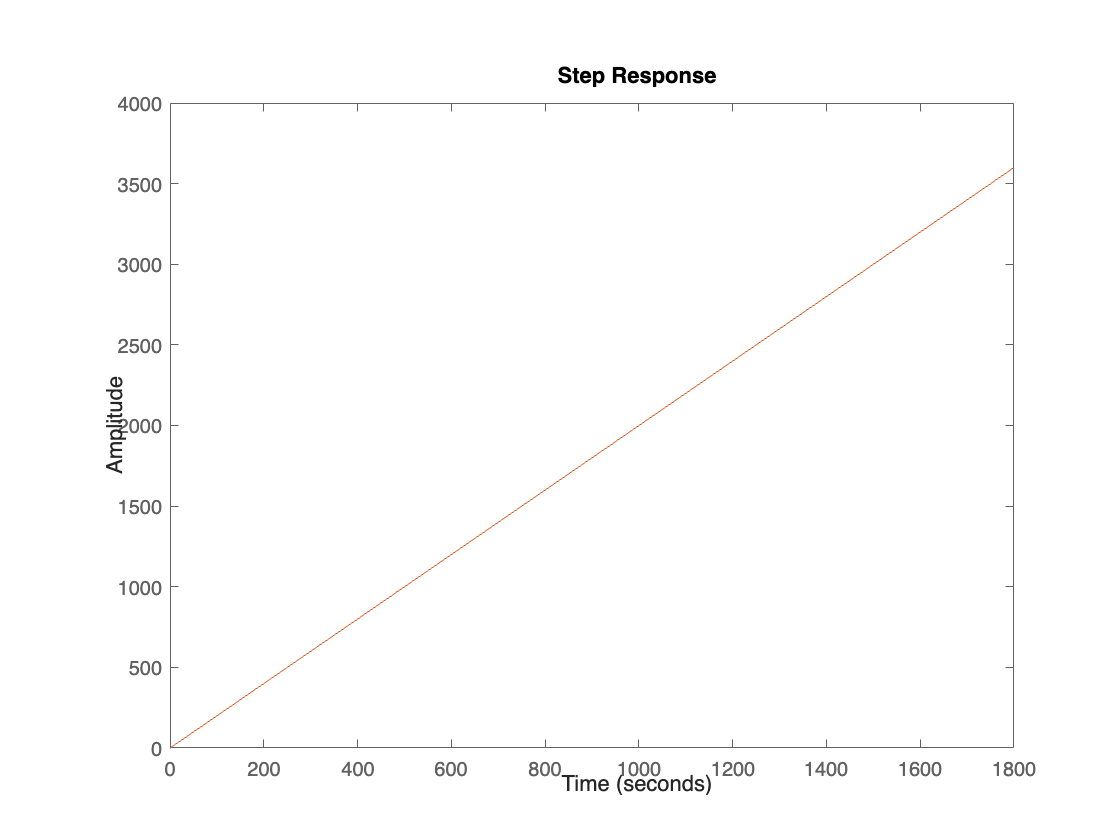


sp2 =

	resppack.timeplot



sp2 = stepplot(sys2, G2)

As can be seen in this graph, the output position magnitude keeps rising linearly. This also appears feasible given that we have a constant positive nonzero amplitude of the velocity after approximately 1,2s. If the velocity is always positive, the position will keep increasing unless some holonomic constraint prevents it from doing so. 

### Pole-zero plots

Furthermore the pole zero plots of the systems were graphed. 

Pole zero plot for system with velocity as output:

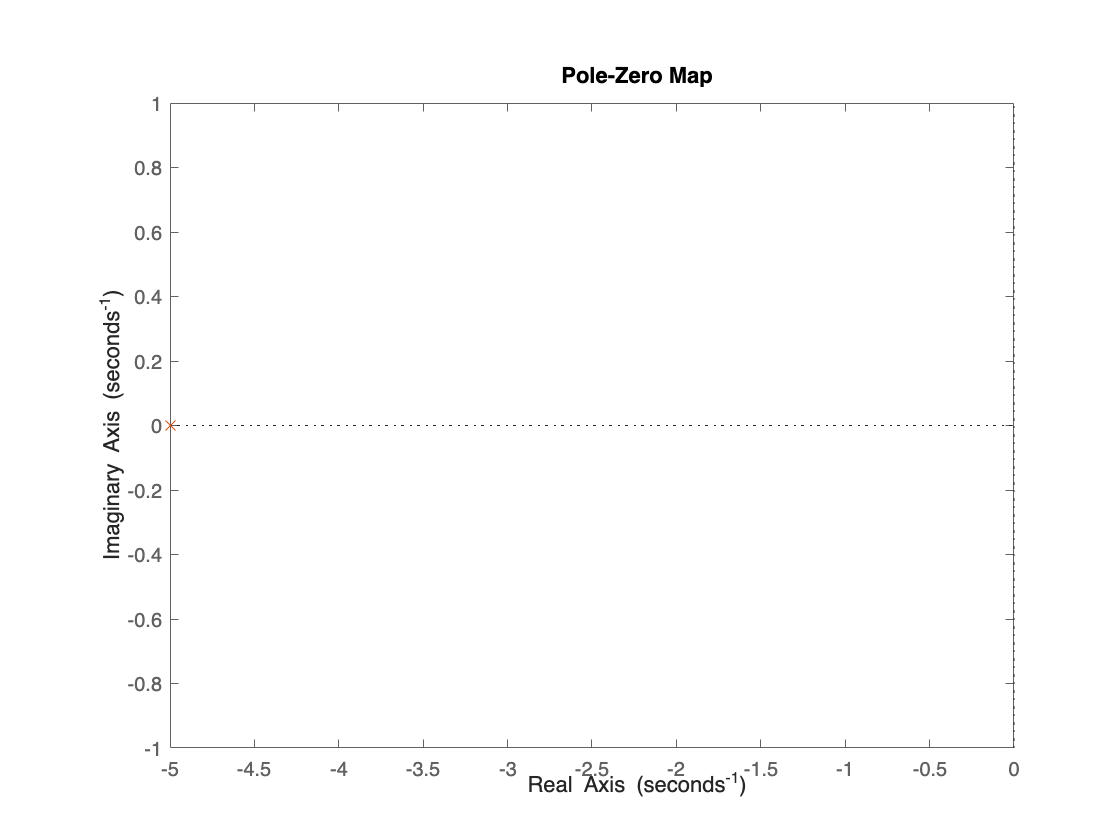


pzp =

	resppack.mpzplot



pzp = pzplot(sys1, G1)

As can be seen in the graph, the system has only one pole on the real axis at -5, and no zeroes. This is also what makes the step response converge to a value as time passes. 

The pole zsero plot of the system with position as output:

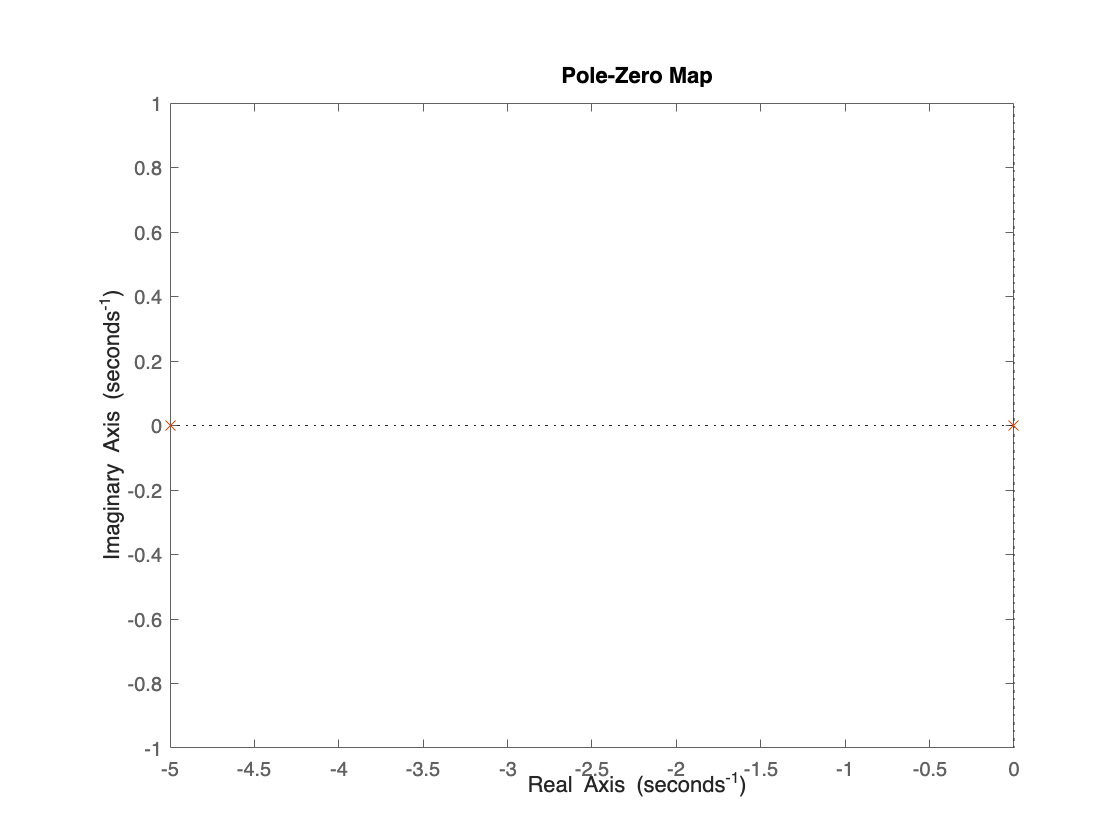


pzp2 =

	resppack.mpzplot



pzp2 = pzplot(sys2, G2)

As can be seen in this graph, the system has two poles, one at -5 and one at 0, the system has no zeroes. This shows that the system is marginally stable, and that in a continous time system the response of the system to a step input will not grow or decay, it will be a ramp. This is specifically the behavior shown in the step response plot for the system with position as output. 

### DC-gain

As can be seen in the step response graphs of the first system with the velocity as output, the amplitude approaches 2 as time increases. The DC-gain of a system is defined in the time domain as $K_{DC} = \lim_{t \to \infty} y(t)
$. In the first system, the graph shows that this DC-gain is 2. 

Calculating the same DC-gain by using the transfer function of the first system and the definition of DC-gain in the s-domain $K_{DC} = G(0) = \lim_{s \to 0} G(s)
$ we find that when inputing $s = 0$ into $G_1(s) = \frac{1}{m s + d}
$ we get $G_1(0) = \frac{1}{d} = 2
$ when d is defined as $d = 0,5 Ns/m$. 

The DC-gain for the second system with the position as output can also be found by studying the step response graph for this system. Here, the graph keeps increasing linearly and does not reach a finite value. Hence, this system has infinite DC-gain. 

Calculating this by using the transfer function of the first system and the definition of DC-gain in the s-domain $K_{DC} = G(0) = \lim_{s \to 0} G(s)
$ we find that when inputing $s = 0$ into $G_2(s) = \frac{1}{m s^2 + d s}

$ we get $G_2(s) = \frac{1}{0} = \infty

$. 

### System time constant

For the first system with velocity as output, the final amplitude value once settled is 2. The time constant is defined as $y(\tau) = 0.632 \, y_{\text{final}} = 1.264
$. Studying the step response graph, this value seems to be reached at approximately $0,2s$. 

Calculating the value can be done by using the formula $\tau = \frac{1}{|\text{Re}(p)|}
$ where p is the systems pole.  With $Re(p) = -5$ as seen in the pole-zero diagram we find that $\tau = 0,2s $ as found in the graph. 

For the second system with position as output, we have no well defined time constant as the system does not reach a final value. The time constant of the system can be said to be $\tau = \infty$.

### Simulink

Transfer function and block diagram model of first system with velocity as output and a step input

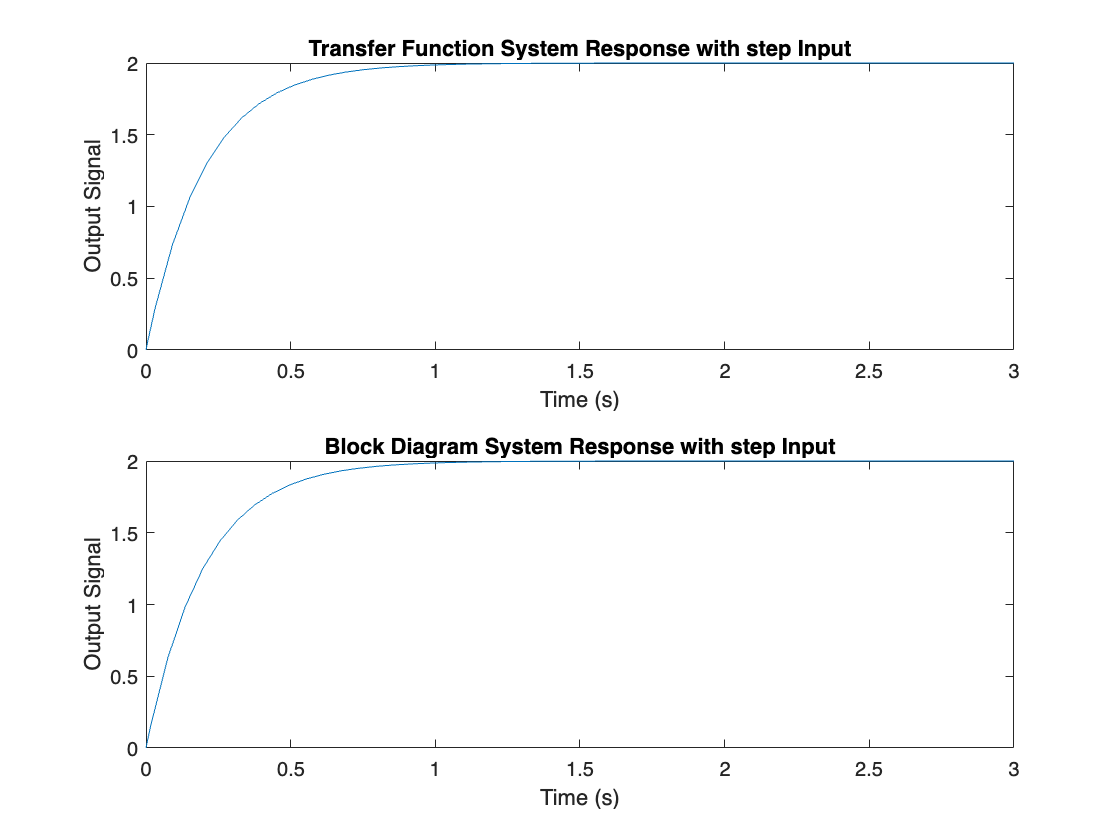

% Define the Simulink model name
model_name = 'excercise1_tf1'; % Replace with your actual model name
load_system(model_name);

% Set the simulation stop time
set_param(model_name, 'StopTime', '2'); % Adjust simulation time as needed

% Choose input type: 'step' or 'sine'
input_type = 'step';

% Configure the input signal based on type
switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        % Set the switch to Sine input
        set_param([model_name '/switchval'], 'Value', '0');
        
        % Configure Sine Wave block parameters
        frequency = 1; % Frequency of sine wave in Hz
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); % Frequency in rad/s
end

% Run the simulation
simOut = sim(model_name);

% Retrieve and plot the output if needed
sim_time1 = simOut.tout;
output_signal1 = simOut.logsout.getElement('velocity').Values.Data; % Replace 'output_signal' with your signal name

% Define the Simulink model name
model_name = 'excercise1_bd1'; % Replace with your actual model name
load_system(model_name);

% Set the simulation stop time
set_param(model_name, 'StopTime', '2'); % Adjust simulation time as needed

% Choose input type: 'step' or 'sine'
input_type = 'step';

% Configure the input signal based on type
switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        % Set the switch to Sine input
        set_param([model_name '/switchval'], 'Value', '0');
        
        % Configure Sine Wave block parameters
        frequency = 1; % Frequency of sine wave in Hz
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); % Frequency in rad/s
end

% Run the simulation
simOut = sim(model_name);

% Retrieve and plot the output if needed
sim_time2 = simOut.tout;
output_signal2 = simOut.logsout.getElement('velocity').Values.Data; % Replace 'output_signal' with your signal name

figure;
subplot(2,1,1);
plot(sim_time1, output_signal1);
title(['Transfer Function System Response with ' input_type ' Input']);
xlabel('Time (s)');
ylabel('Output Signal');
subplot(2,1,2);
plot(sim_time2, output_signal2);
title(['Block Diagram System Response with ' input_type ' Input']);
xlabel('Time (s)');
ylabel('Output Signal');

Transfer function and block diagram model of second system with position as output and a step input

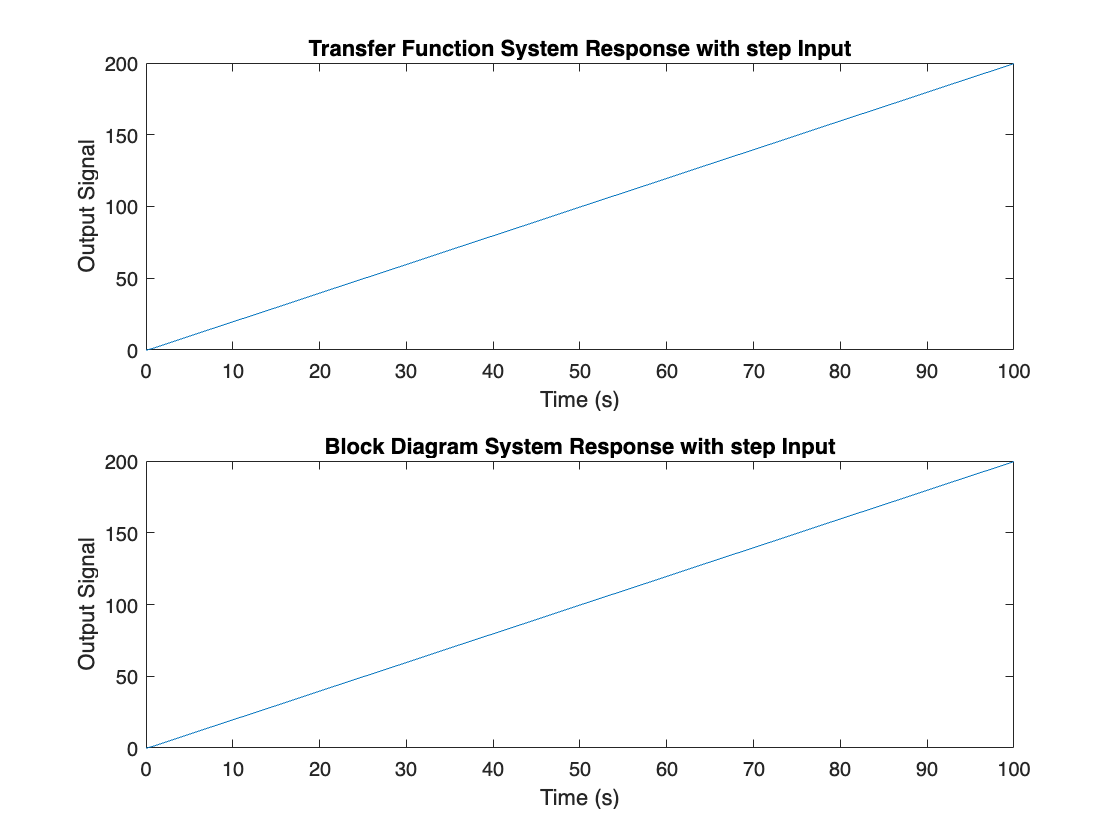

% Define the Simulink model name
model_name = 'excercise1_tf2'; % Replace with your actual model name
load_system(model_name);

% Set the simulation stop time
set_param(model_name, 'StopTime', '100'); % Adjust simulation time as needed

% Choose input type: 'step' or 'sine'
input_type = 'step';

% Configure the input signal based on type
switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        % Set the switch to Sine input
        set_param([model_name '/switchval'], 'Value', '0');
        
        % Configure Sine Wave block parameters
        frequency = 1; % Frequency of sine wave in Hz
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); % Frequency in rad/s
end

% Run the simulation
simOut = sim(model_name);

% Retrieve and plot the output if needed
sim_time1 = simOut.tout;
output_signal1 = simOut.logsout.getElement('position').Values.Data; % Replace 'output_signal' with your signal name

% Define the Simulink model name
model_name = 'excercise1_bd2'; % Replace with your actual model name
load_system(model_name);

% Set the simulation stop time
set_param(model_name, 'StopTime', '100'); % Adjust simulation time as needed

% Choose input type: 'step' or 'sine'
input_type = 'step';

% Configure the input signal based on type
switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        % Set the switch to Sine input
        set_param([model_name '/switchval'], 'Value', '0');
        
        % Configure Sine Wave block parameters
        frequency = 1; % Frequency of sine wave in Hz
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); % Frequency in rad/s
end

% Run the simulation
simOut = sim(model_name);

% Retrieve and plot the output if needed
sim_time2 = simOut.tout;
output_signal2 = simOut.logsout.getElement('position').Values.Data; % Replace 'output_signal' with your signal name

figure;
subplot(2,1,1);
plot(sim_time1, output_signal1);
title(['Transfer Function System Response with ' input_type ' Input']);
xlabel('Time (s)');
ylabel('Output Signal');
subplot(2,1,2);
plot(sim_time2, output_signal2);
title(['Block Diagram System Response with ' input_type ' Input']);
xlabel('Time (s)');
ylabel('Output Signal');

Transfer function and block diagram model of first system with velocity as output and a sinus input of frequency 1 rad/s

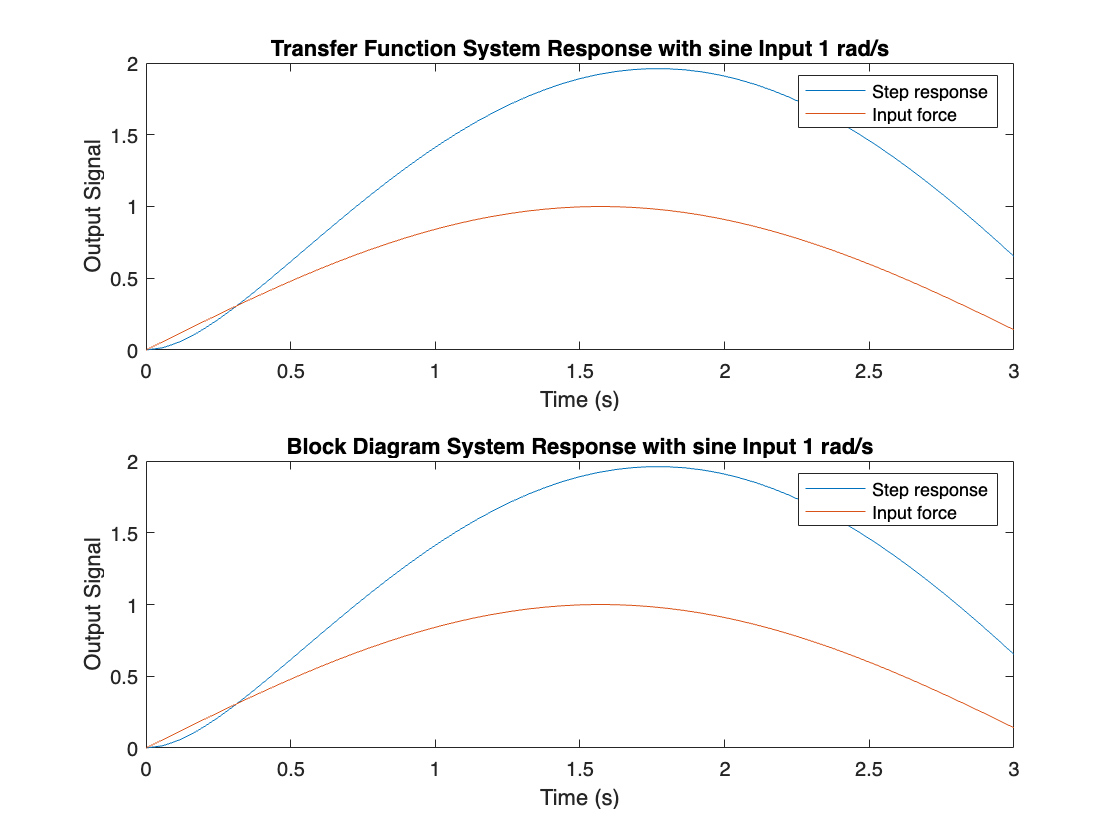

% Define the Simulink model name
model_name = 'excercise1_tf1'; % Replace with your actual model name
load_system(model_name);

% Set the simulation stop time
set_param(model_name, 'StopTime', '3'); % Adjust simulation time as needed

% Choose input type: 'step' or 'sine'
input_type = 'sine';

% Configure the input signal based on type
switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        % Set the switch to Sine input
        set_param([model_name '/switchval'], 'Value', '0');
        
        % Configure Sine Wave block parameters
        frequency = num2str(1); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); % Frequency in rad/s
end

% Run the simulation
simOut = sim(model_name);

% Retrieve and plot the output if needed
sim_time1 = simOut.tout;
output_signal1 = simOut.logsout.getElement('velocity').Values.Data; % Replace 'output_signal' with your signal name
input_force1 = simOut.logsout.getElement('force').Values.Data;

% Define the Simulink model name
model_name = 'excercise1_bd1'; % Replace with your actual model name
load_system(model_name);

% Set the simulation stop time
set_param(model_name, 'StopTime', '3'); % Adjust simulation time as needed

% Choose input type: 'step' or 'sine'
input_type = 'sine';

% Configure the input signal based on type
switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        % Set the switch to Sine input
        set_param([model_name '/switchval'], 'Value', '0');
        
        % Configure Sine Wave block parameters
        frequency = num2str(1); % Frequency of sine wave in Hz
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); % Frequency in rad/s
end

% Run the simulation
simOut = sim(model_name);

% Retrieve and plot the output if needed
sim_time2 = simOut.tout;
output_signal2 = simOut.logsout.getElement('velocity').Values.Data; % Replace 'output_signal' with your signal name
input_force2 = simOut.logsout.getElement('force').Values.Data;

figure;
subplot(2,1,1);
plot(sim_time1, output_signal1);
title(['Transfer Function System Response with ' input_type ' Input 1 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time1, input_force1);
legend("Step response", "Input force")
hold off

subplot(2,1,2);
plot(sim_time2, output_signal2);
title(['Block Diagram System Response with ' input_type ' Input 1 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time2, input_force2);
legend("Step response", "Input force")
hold off

Transfer function and block diagram model of first system with velocity as output and a sinus input of frequency 10 rad/s

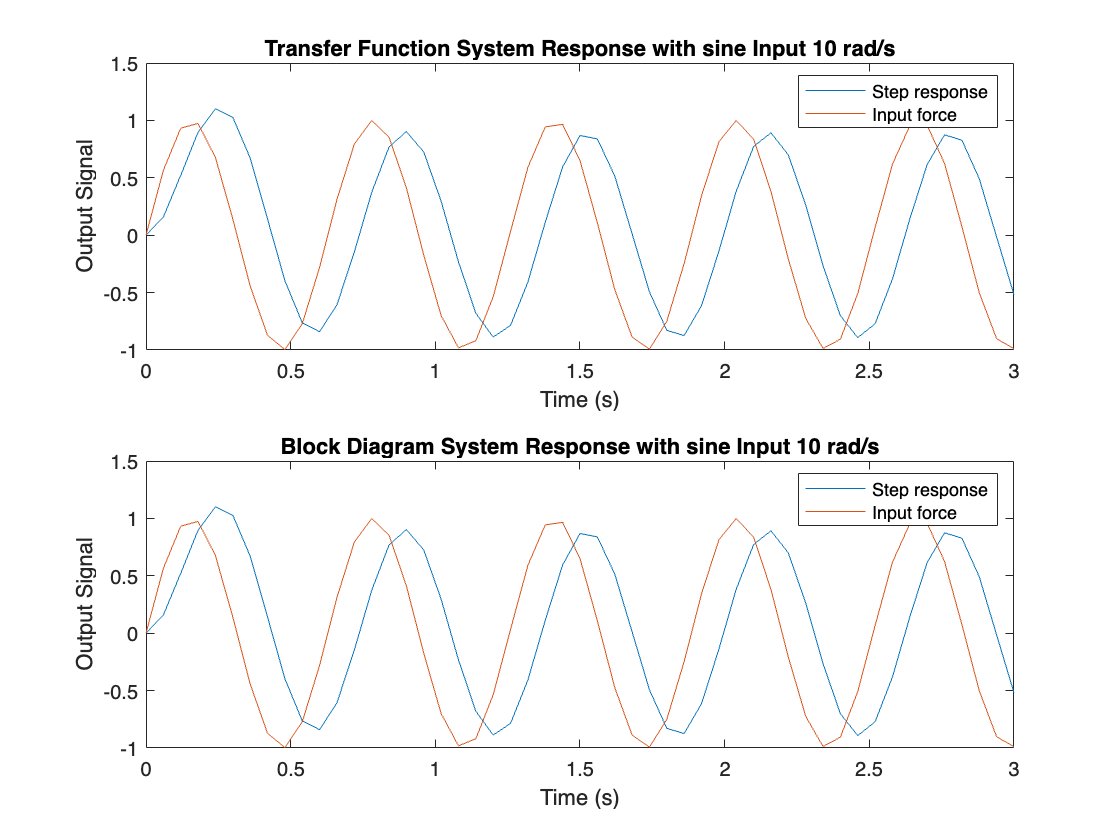

model_name = 'excercise1_tf1';
load_system(model_name);

set_param(model_name, 'StopTime', '3');

% Choose input type: 'step' or 'sine'
input_type = 'sine';

switch input_type
    case 'step'
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        set_param([model_name '/switchval'], 'Value', '0');
        
        frequency = num2str(10);
        set_param([model_name '/Sine Wave'], 'Frequency', frequency);
end

% Run the simulation
simOut = sim(model_name);

% Retrieve and plot the output if needed
sim_time1 = simOut.tout;
output_signal1 = simOut.logsout.getElement('velocity').Values.Data;
input_force1 = simOut.logsout.getElement('force').Values.Data;

model_name = 'excercise1_bd1'; 
load_system(model_name);

set_param(model_name, 'StopTime', '3'); % 

input_type = 'sine';

switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        set_param([model_name '/switchval'], 'Value', '0');
        
        frequency = num2str(10); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency);
end

simOut = sim(model_name);

% Retrieve and plot the output
sim_time2 = simOut.tout;
output_signal2 = simOut.logsout.getElement('velocity').Values.Data;
input_force2 = simOut.logsout.getElement('force').Values.Data;

figure;
subplot(2,1,1);
plot(sim_time1, output_signal1);
title(['Transfer Function System Response with ' input_type ' Input 10 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time1, input_force1);
legend("Step response", "Input force")
hold off

subplot(2,1,2);
plot(sim_time2, output_signal2);
title(['Block Diagram System Response with ' input_type ' Input 10 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time2, input_force2);
legend("Step response", "Input force")
hold off

Transfer function and block diagram model of second system with position as output and a sinus input of frequency 1 rad/s

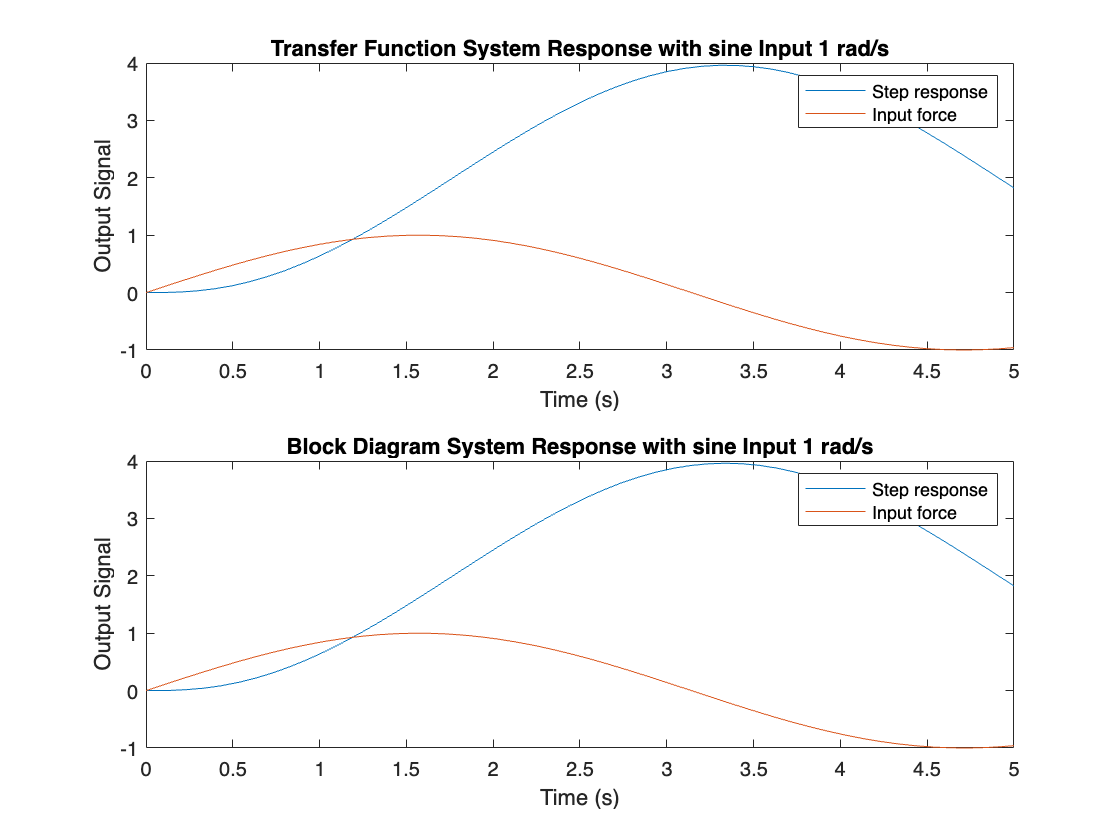

% Define the Simulink model name
model_name = 'excercise1_tf2'; % Replace with your actual model name
load_system(model_name);

% Set the simulation stop time
set_param(model_name, 'StopTime', '5'); % Adjust simulation time as needed

% Choose input type: 'step' or 'sine'
input_type = 'sine';

% Configure the input signal based on type
switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        % Set the switch to Sine input
        set_param([model_name '/switchval'], 'Value', '0');
        
        % Configure Sine Wave block parameters
        frequency = num2str(1); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); % Frequency in rad/s
end

% Run the simulation
simOut = sim(model_name);

% Retrieve and plot the output if needed
sim_time1 = simOut.tout;
output_signal1 = simOut.logsout.getElement('position').Values.Data; % Replace 'output_signal' with your signal name
input_force1 = simOut.logsout.getElement('force').Values.Data;

% Define the Simulink model name
model_name = 'excercise1_bd2'; % Replace with your actual model name
load_system(model_name);

% Set the simulation stop time
set_param(model_name, 'StopTime', '5'); % Adjust simulation time as needed

% Choose input type: 'step' or 'sine'
input_type = 'sine';

% Configure the input signal based on type
switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        % Set the switch to Sine input
        set_param([model_name '/switchval'], 'Value', '0');
        
        % Configure Sine Wave block parameters
        frequency = num2str(1); % Frequency of sine wave in Hz
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); % Frequency in rad/s
end

% Run the simulation
simOut = sim(model_name);

% Retrieve and plot the output if needed
sim_time2 = simOut.tout;
output_signal2 = simOut.logsout.getElement('position').Values.Data; % Replace 'output_signal' with your signal name
input_force2 = simOut.logsout.getElement('force').Values.Data;

figure;
subplot(2,1,1);
plot(sim_time1, output_signal1);
title(['Transfer Function System Response with ' input_type ' Input 1 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time1, input_force1);
legend("Step response", "Input force")
hold off

subplot(2,1,2);
plot(sim_time2, output_signal2);
title(['Block Diagram System Response with ' input_type ' Input 1 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time2, input_force2);
legend("Step response", "Input force")
hold off

Transfer function and block diagram model of second system with position as output and a sinus input of frequency 10 rad/s

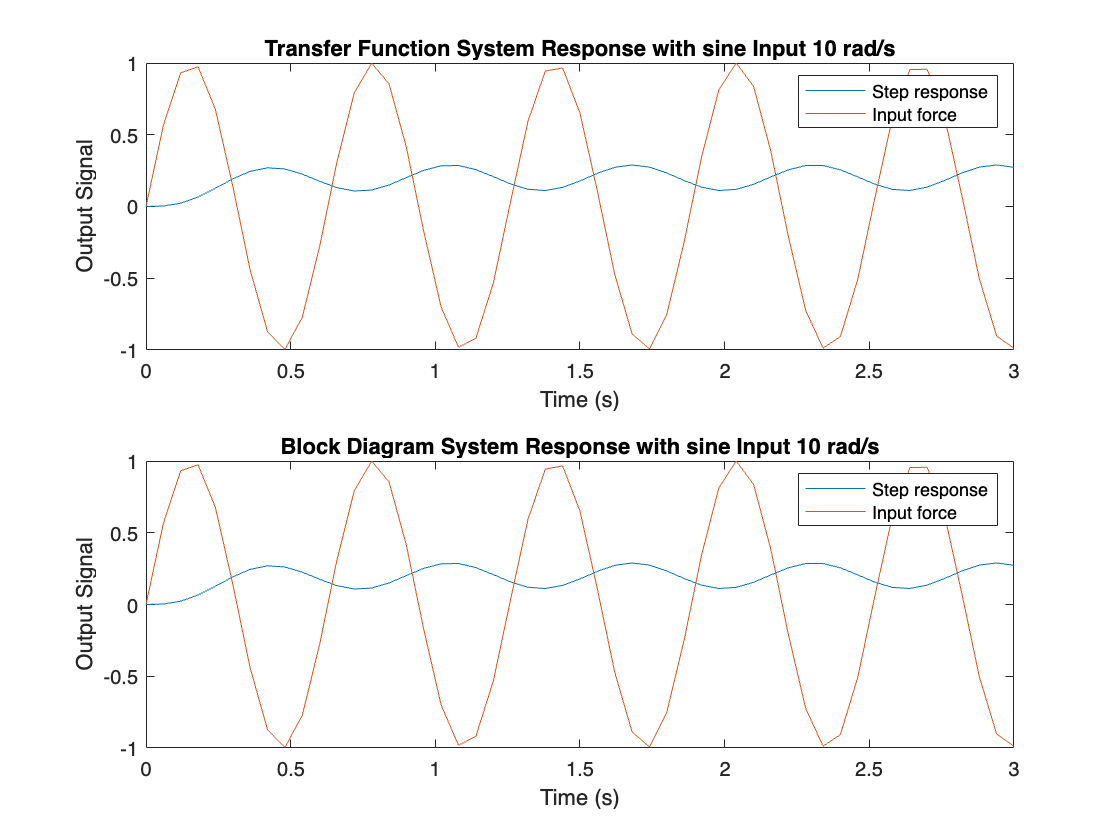

model_name = 'excercise1_tf2';
load_system(model_name);

set_param(model_name, 'StopTime', '3');

% Choose input type: 'step' or 'sine'
input_type = 'sine';

switch input_type
    case 'step'
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        set_param([model_name '/switchval'], 'Value', '0');
        
        frequency = num2str(10);
        set_param([model_name '/Sine Wave'], 'Frequency', frequency);
end

% Run the simulation
simOut = sim(model_name);

% Retrieve and plot the output if needed
sim_time1 = simOut.tout;
output_signal1 = simOut.logsout.getElement('position').Values.Data;
input_force1 = simOut.logsout.getElement('force').Values.Data;

model_name = 'excercise1_bd2'; 
load_system(model_name);

set_param(model_name, 'StopTime', '3'); % 

input_type = 'sine';

switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        set_param([model_name '/switchval'], 'Value', '0');
        
        frequency = num2str(10); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency);
end

simOut = sim(model_name);

% Retrieve and plot the output
sim_time2 = simOut.tout;
output_signal2 = simOut.logsout.getElement('position').Values.Data;
input_force2 = simOut.logsout.getElement('force').Values.Data;

figure;
subplot(2,1,1);
plot(sim_time1, output_signal1);
title(['Transfer Function System Response with ' input_type ' Input 10 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time1, input_force1);
legend("Step response", "Input force")
hold off

subplot(2,1,2);
plot(sim_time2, output_signal2);
title(['Block Diagram System Response with ' input_type ' Input 10 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time2, input_force2);
legend("Step response", "Input force")
hold off